# Navigate mobile robot using D*

Copyright (C) 1993-2018, by Peter I. Corke, http://www.petercorke.com

Our robot will operate within a grid world that contains free space where it can drive and obstacles.  We load a map of the world

load map1

which loads a variable called map

about map

map [double] : 100x100 (80.0 kB)


The elements of the obstacle map are converted into traversibility values, an obstacle has an infinite traversibility while free space has a nominal traversibility of 1.

Now we create an instance of a robot with the D* navigation algorithm

dstar = Dstar(map, 'quiet');

Now we define the goal and start coordinates

goal = [50,30];
start = [20, 10];

then plan a path to goal (it will take few seconds)

tic; dstar.plan(goal); toc

10558 iterations
Elapsed time is 2.201273 seconds.


Now we can display the obstacles and the cost to reach the goal from every point in the world

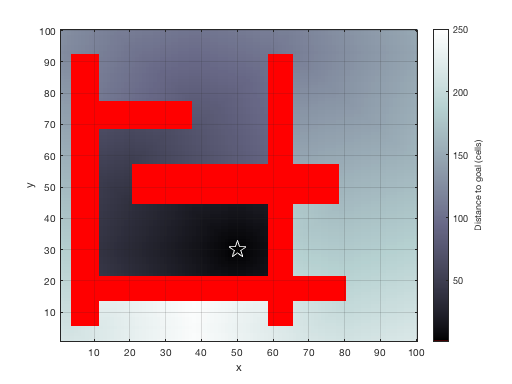

clf; dstar.plot()

where the cost scale is shown by the bar to the right.

Now we can execute the planned path, it will be animated with green dots

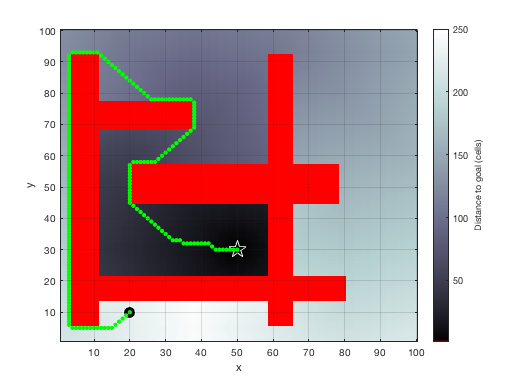

dstar.query(start, 'animate')

Now lets change the difficulty of some of the terrain, make it more costly to traverse

for r=78:85
    for c=12:45
        dstar.modify_cost([c; r], 2); 
    end
end

Now we can replan, but D* does this in an incremental way which is faster than recomputing the whole plan from scratch

tic; dstar.plan(); toc

3179 iterations
Elapsed time is 1.554903 seconds.


that took less time than before...  The best path is now

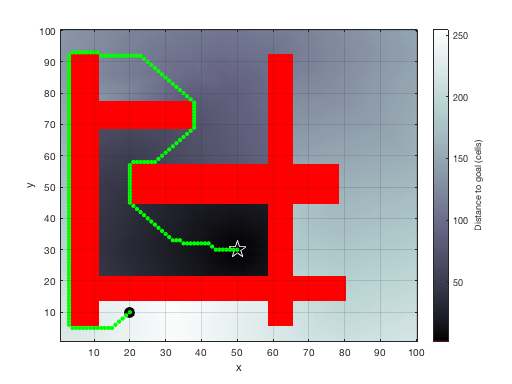

dstar.query(start, 'animate')

we can see that the path has avoided the high cost region we added.